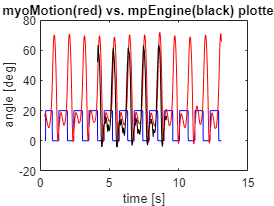

clc;
close;
clear;

load("mp_engine_LT_KneeFlex.mat"); %video mpEngine
load("myoMotion_LT_KneeFlex.mat"); %IMU                 %signal_73=KneeFlexLT
load("myoMotion_ContactSignal.mat"); %contact signal created by the IMUs
load('intervals.mat')
%load in the Vectors as vars
data_mp = tempRaw_Signal;
data_myoMotion = rec.record_2015_06_23_17_45_Treadmill_Gait_with_MyoMotion___EMG____.movements.sources(4).signals.signal_73.data;
data_contact = tempRawContact_Signal;
data_intervals = intervals;
%clear the loads
clear rec tempRaw_Signal tempRawContact_Signal intervals;

load("mp_engine_RT_KneeFlex_gaps.mat");
load("myoMotion_ContactSignal_relatedToGaps.mat");

data_mp_gap = tempRaw_Signal;
data_contact_gap = tempRawContact_Signal;
clear rec tempRaw_Signal tempRawContact_Signal intervals;
%sampleFrequency of the signals
fs_mm = 100;    %freq [Hz] myoMotion
fs_mp = 30;     %freq [Hz] mpEngine
fs_mm_gap = 200;    %freq [Hz] myoMotion
fs_mp_gap = 120;    %freq [Hz] mpEngine
 
%sampleTime of the signals
T_mm = 1/fs_mm;    %samplingTime [s] myoMotion
T_mp = 1/fs_mp;    %samplingTime [s] mpEngine
T_mm_gap = 1/fs_mm_gap;    %samplingTime [s] myoMotion
T_mp_gap = 1/fs_mp_gap;    %samplingTime [s] mpEngine
%synchronization offSets
timeOffSet_mm = 0.34;       %[s] *
timeOffSet_mp = 0.4233;     %[s] *both taken from records field: "begin_time"
timeOffSet_mm_gap = 1.15;       %[s] *
timeOffSet_mp_gap = 1.0125;     %[s] *both taken from records field: "begin_time"
%dataLenghts
L_mm = length(data_myoMotion);
L_mp = length(data_mp);
L_mm_gap = length(data_contact_gap);
L_mp_gap = length(data_mp_gap); 
%timeVectors
t_mm = linspace(0,L_mm,L_mm).*T_mm + timeOffSet_mm; % time vector
t_mp = linspace(0,L_mp,L_mp).*T_mp + timeOffSet_mm; % time vector
t_mm_gap = linspace(0,L_mm_gap,L_mm_gap).*T_mm_gap + timeOffSet_mm_gap; % time vector
t_mp_gap = linspace(0,L_mp_gap,L_mp_gap).*T_mp_gap + timeOffSet_mp_gap; % time vector

%plot signals with time vectors
figure;
plot(t_mm,data_contact/50, 'b')
title("compare myoMotion(red) vs. mpEngine(black) plotted over time")
hold on;
plot(t_mm, data_myoMotion, 'r'); %myoMotion Data in Red
plot(t_mp, data_mp, 'k'); %mpEngine Data in black
xlabel("time [s]");
ylabel("angle [deg]");
hold off;

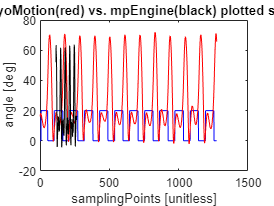

%plot signals with samplingpoints
figure;
plot(data_contact/50, 'b')
title("compare myoMotion(red) vs. mpEngine(black) plotted samplingRates")
hold on;
plot(data_myoMotion, 'r'); %myoMotion Data in Red
plot(data_mp, 'k'); %mpEngine Data in black
xlabel("samplingPoints [unitless]");
ylabel("angle [deg]");
hold off;

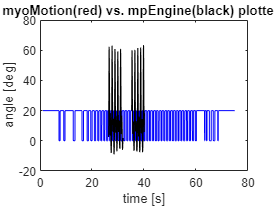


%plot signals with time vectors
figure;
plot(t_mm_gap,data_contact_gap/50, 'b')
title("compare myoMotion(red) vs. mpEngine(black) plotted over time")
hold on;
% plot(t_mm_gap, data_myoMotion_gap, 'r'); %myoMotion Data in Red
plot(t_mp_gap, data_mp_gap, 'k'); %mpEngine Data in black
xlabel("time [s]");
ylabel("angle [deg]");
hold off;

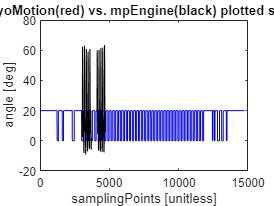

%plot signals with samplingpoints
figure;
plot(data_contact_gap/50, 'b')
title("compare myoMotion(red) vs. mpEngine(black) plotted samplingRates")
hold on;
% plot(data_contact_gap, 'r'); %myoMotion Data in Red
plot(data_mp_gap, 'k'); %mpEngine Data in black
xlabel("samplingPoints [unitless]");
ylabel("angle [deg]");
hold off;


% normalizedStride = normalize_strides(data_mp,data_contact,data_intervals)

% figure;
% plot(normalizedStride);

